## Load input

[input, Fs] = audioread("guitar_sample.mp3");
Fnyq = Fs / 2;
input = sum(input, 2) / 2; % Stero to mono
input_duration = 8;
% Fragmento de input_duration segundos
%input = input(1:floor(input_duration*Fs));

input = zeros(2000,1);
input(1) = 1;
%input(50:50:1000) = 1;

## Low pass whole

wp = 2000;
[b,a] = cheby2(4, 60, wp/Fnyq);
sos = tf2sos(b,a);
y = sosfilt(sos, input);
audiowrite('output_whole.wav', y, Fs);

## Low pass iterative with overlap (incorrect, not passing internal filter state along)

wp = 2000;
[b,a] = cheby2(4, 60, wp/Fnyq);
sos = tf2sos(b,a);

L = 1000;
P = L*0.5;
y2 = zeros(length(input),1);
iter_count=ceil(length(input)/(L-P));

for i=1:iter_count    
    lower_bound = (i-1)*(L-P) + 1;
    upper_bound = min(lower_bound + L - 1, length(input));
    frame = input(lower_bound:upper_bound);
    y_frame = sosfilt(sos, frame);
    
    
    upper_bound_2 = min(lower_bound+P-1, length(y2));
    y2(lower_bound:upper_bound_2) =...
        y2(lower_bound:upper_bound_2)...
        + y_frame(1:min(P, length(y_frame))) / 2;
    lower_bound_2 = min(lower_bound+P, length(y2));
    lower_bound_3 = min(P+1, length(y_frame));
    y2(lower_bound_2:upper_bound) =...
        y_frame(lower_bound_3:end);
end

audiowrite('output_iterative.wav', y2, Fs);

## Low pass iterative correct (passing internal state filter along)

wp = 2000;
[b,a] = cheby2(4, 60, wp/Fnyq);
zf = [];
sos = tf2sos(b,a);

L = 1000;
iter_count=ceil(length(input)/(L-P));
y2 = [];
for i=1:iter_count    
    input_index = (i-1)*L + 1;
    [y_frame, zf] = filter(b,a,input(input_index: min(input_index+L-1, length(input))),zf);
    y2 = [y; y_frame];
end

audiowrite('output_iterative.wav', y2, Fs);

## Plots

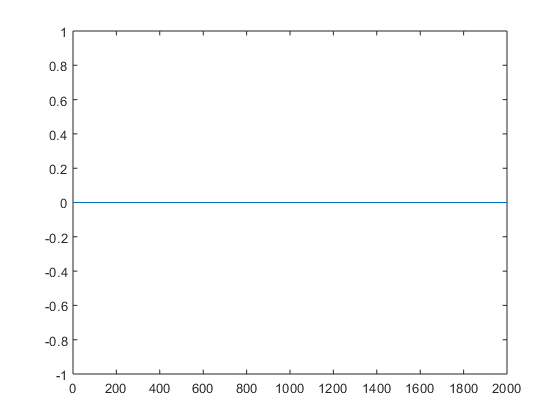

plot(y-y2)

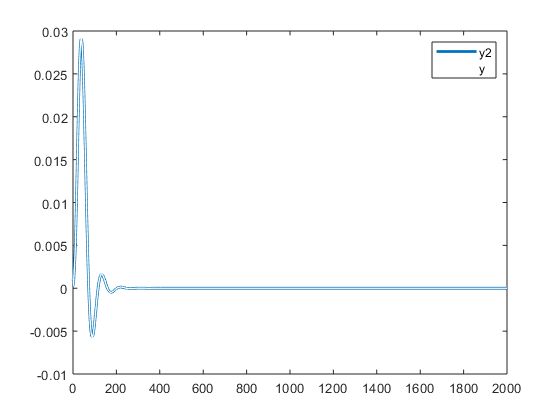

figure
plot(y2,'DisplayName','y2','LineWidth',2);hold on;plot(y,'DisplayName','y','LineWidth',1,'Color','white');hold off;
legend